## Preamble and settings

run plant1.m
the = (0:1:360)*pi/180;

[numRows,numCols,lenW,~] = size(Pw);

T = (eye(2)+P*Go)\P*Go*Fo;
Tw = freqresp(T,W);
Mw_ = Tw;

## Generate $C$ and $R$ matrices

GAM = ones(numRows,numCols,lenW);
GAM(:,:,1) = [1 1; 1 1];


### Set $M(j\omega)$ matrix

isSymmetricPlant = true;

Mw_ = zeros(numRows,numCols,lenW,N);
for w_index=1:lenW
    for p_index=1:N
        for row=1:numRows
                phi = rand*2*pi;
                if isSymmetricPlant==true
                    Mw_(1,1,w_index,p_index) = Mw(1,1,w_index)+Bw(1,1,w_index)/2*exp(1i*phi);
                    Mw_(2,2,w_index,p_index) = Mw_(1,1,w_index,p_index);
                    break
                else
                    Mw_(row,row,w_index,p_index) = Mw(row,row,w_index)+Bw(row,row,w_index)/2*exp(1i*phi);
                end
        end
    end
end

Cw = zeros(numRows,numCols,lenW,(N^2-N)/2);
Rw = Cw;

for w_index=1:lenW
    ind = 0;
    for pi_index=1:N
        Qi = Qw(:,:,w_index,pi_index);
        Mi = Mw_(:,:,w_index,pi_index);

        for pk_index=1:N
            if pi_index == pk_index
                break
            end
            Qk = Qw(:,:,w_index,pk_index);
            Mk = Mw_(:,:,w_index,pk_index);

            ind = ind+1;
            Cw(:,:,w_index,ind) = -( Qi*Mi-Qk*Mk )/(Mi-Mk);
            Rw(:,:,w_index,ind) = GAM(:,:,w_index) * abs( inv(Mi-Mk) );
        end
    end
end

## Determine boundaries

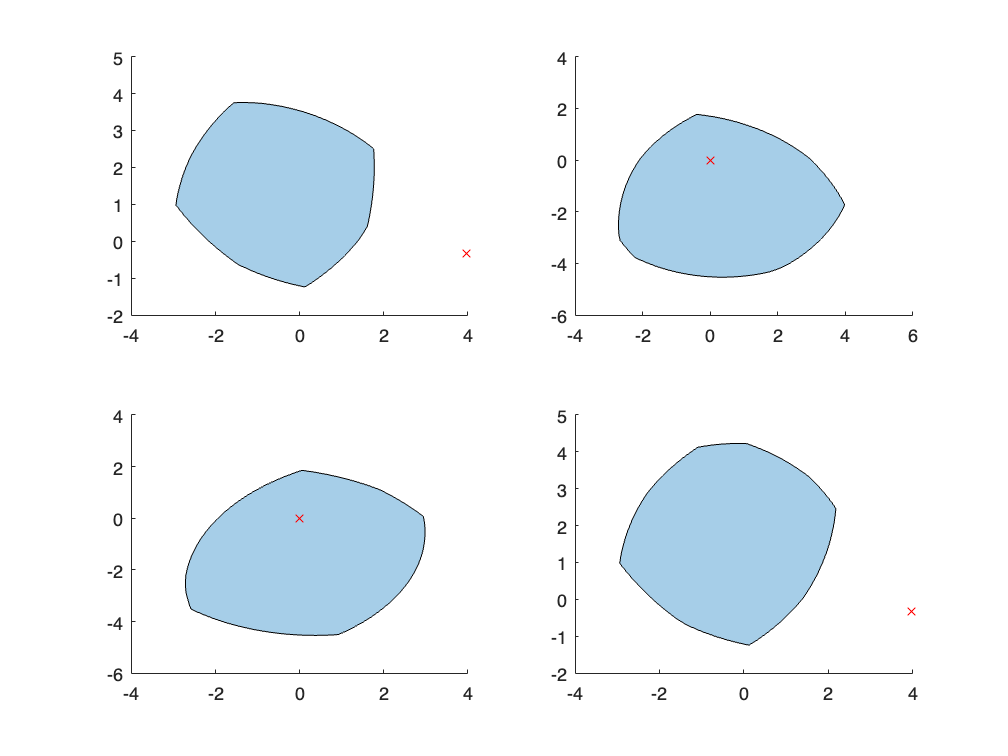


Delta = 10*ones(numRows,numCols,lenW);

Delta(:,:,1) = 1*ones(2,2);
Delta(:,:,2) = 2*ones(2,2);
Delta(:,:,3) = 4*ones(2,2);
Delta(:,:,5) = 30*ones(2,2);
Delta(:,:,6) = 55*ones(2,2);

[polyG,polyG_int,bnd] = getStayInDiscs(the,Cw,Rw,Delta);

w_index = 1;
Gw = squeeze( freqresp(Go,W(w_index)) );

figure
for row=1:numRows
    for col=1:numCols
        ind = 2*(row-1)+col;
        subplot(numRows,numCols,ind), hold on
        plot(polyG_int(row,col,w_index))

        plot( real(Gw(row,col,w_index)), imag(Gw(row,col,w_index)),'rx' )
    end
end

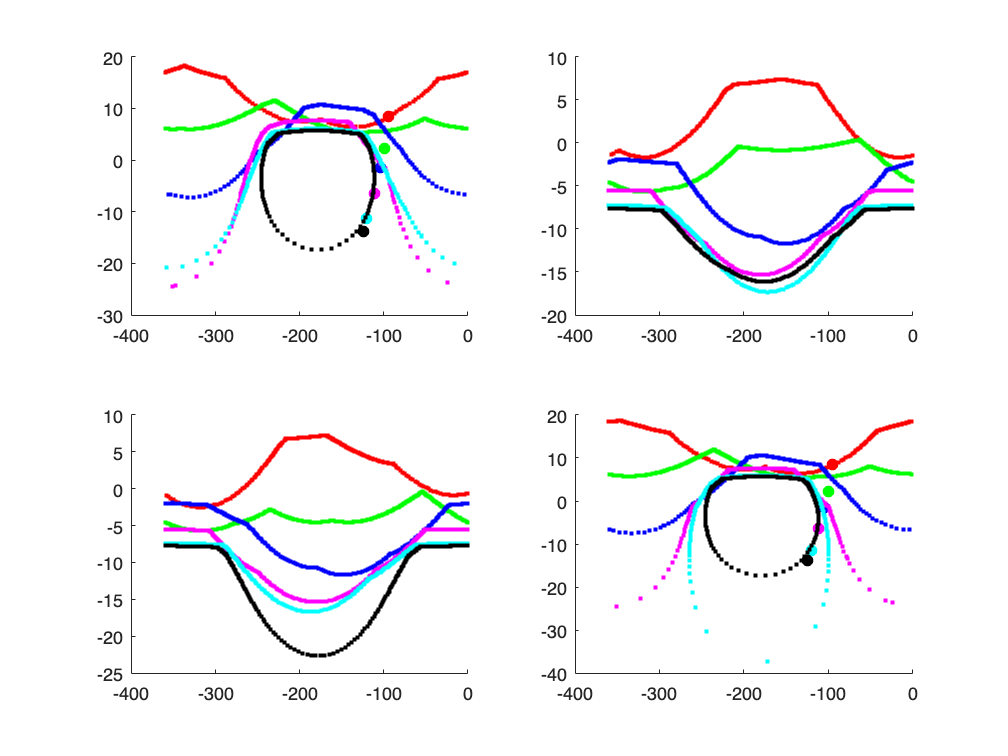


Po = P(:,:,1);
G_ = .33*Go;
plotLogPolarBounds(bnd,Po,G_,W)

### X test

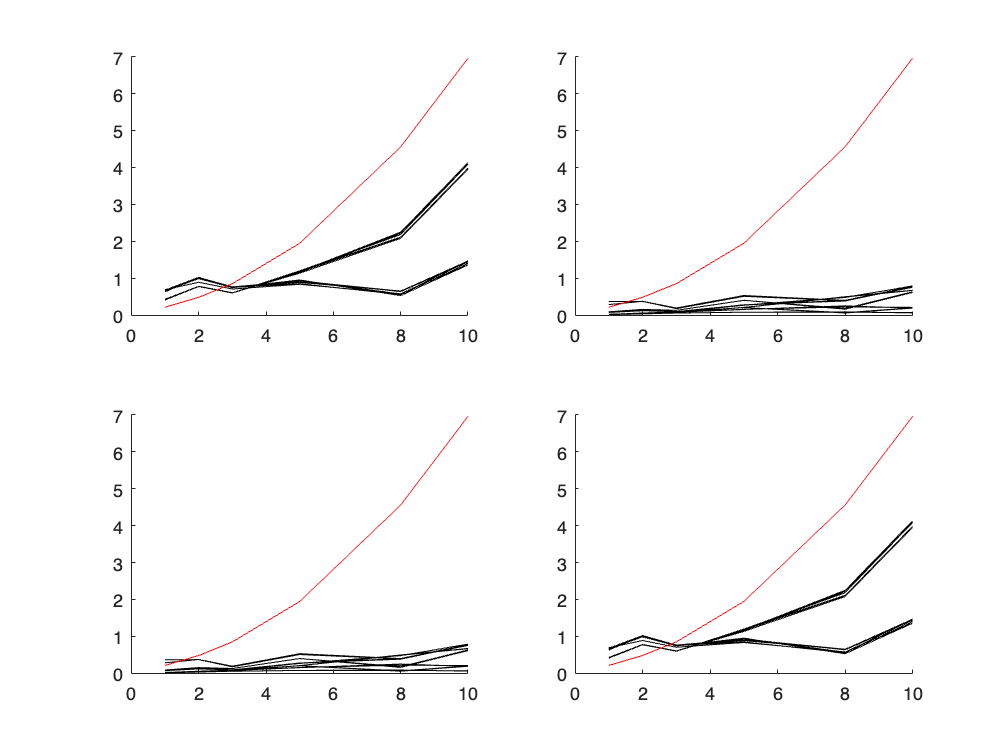

Gw = freqresp(G_,W);
Xw = zeros(numRows,numCols,lenW);
Ew = zeros(numRows,numCols,lenW,N);

ind = 16;
for w_index=1:lenW
    Xw(:,:,w_index) = ( Qw(:,:,w_index,ind)+Gw(:,:,w_index) )*Mw_(:,:,w_index,ind)-Gw(:,:,w_index);

    for p_index=1:N
        Ew(:,:,w_index,p_index) = ( eye(2)+Pw(:,:,w_index,p_index)*Gw(:,:,w_index) )\( Mw(:,:,w_index)-Pw(:,:,w_index,p_index)*Xw(:,:,w_index) );
    end
end

figure
for row=1:2
    for col=1:2
        ind = 2*(row-1)+col;
        subplot(numRows,numCols,ind),hold on
        plot(W,squeeze( abs(Ew(row,col,:,:) )),'k')
        plot(W,squeeze( Bw(row,col,:) ),'r')
    end
end